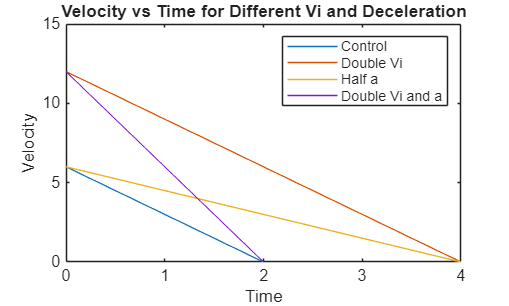

clear
time = 0:1:4;
Vi1 = 6;           %going 60m/s when they first brake
Vi2 = 12;          %initial speed doubles
Vi3 = 6;
Vi4 = 12;          %inital speed doubles
a1 = -3;   %m/s^2      %decelerating at a constant rate
a2 = -3;
a3 = -1.5;             %deceleration is halved
a4 = -6;               %deceleration is doubled

v1 = Vi1 + a1*time;
v2 = Vi2 + a2*time;
v3 = Vi3 + a3*time;
v4 = Vi4 + a4*time;

plot(time, v1);
hold on
plot(time, v2);
plot(time, v3);
plot(time, v4);
hold off
xlabel("Time")
ylabel("Velocity")
title('Velocity vs Time for Different Vi and Deceleration');
legend('Control', 'Double Vi', 'Half a', "Double Vi and a");

% Ensure y-axis does not show negative numbers
yl = ylim;                  % get current y-limits
yl(1) = max(0, yl(1));      % set lower limit to zero (if not already)
ylim(yl);


distance1 = integral(@(time) Vi1 + a1*time, 0, 2);
distance2 = integral(@(time) Vi2 + a2*time, 0, 4);
distance3 = integral(@(time) Vi3 + a3*time, 0, 4);
distance4 = integral(@(time) Vi4 + a4*time, 0, 2);
% Display the calculated distances for each scenario
disp(['Distance for Control:           ', num2str(distance1)]);

Distance for Control:           6


disp(['Distance for Double Vi:         ', num2str(distance2)]);

Distance for Double Vi:         24


disp(['Distance for Half a:            ', num2str(distance3)]);

Distance for Half a:            12


disp(['Distance for Double Vi and a:   ', num2str(distance4)]);

Distance for Double Vi and a:   12


## Analysis

% On the graph above, we can see that the initial velocity and the rate
% of deceleration of a vehicle are directly related. If we increase the 
% initial velocity and the rate of deceleration by the same magnitude, 
% then it takes the same amount of time for the vehicle to come to a 
% stop. 

% However, the safety concern here is the distance traveled. 
% Vehicle 4 is traveling twice as fast as Vehicle 3, but will have to 
% brake four times as hard to stop after the same distance. 
% We can also see that Vehicle 2 is traveling twice as fast as Vehicle
% 1. When braking at the same rate, Vehicle 2 travels four times as far.

% This shows just how unsafe fast driving is; the faster you go, the 
% harder you have to brake to stop at the right time. 
